# Oceanic Plate Cooling

set_demo_defaults

Unlike the continental heat flow, the oceanic heat flow varies systematically as the oceanic plate ages. Computing the thermal structure of the oceanic plate is therefore more interesting and generally a two-dimensional problem.

## Background on oceanic plates

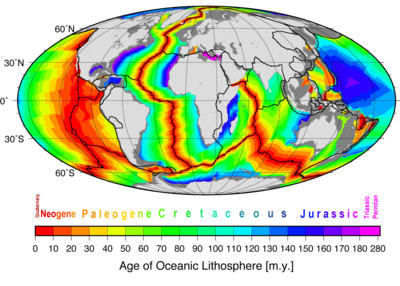

This map from [Mueller et al (2008)](https://agupubs.onlinelibrary.wiley.com/doi/full/10.1029/2007GC001743) shows that the age of the sea floor increases away from the [Mid-Ocean Ridges](https://oceanexplorer.noaa.gov/facts/mid-ocean-ridge.html) (MOR) where it is created by volcanism. The oldest seafloor is in the Pacific ocean (~200 Ma) and a particularly old fragment remains in the Mediterranean (280 Myrs). This makes oceanic crust much younger than the continental crust which largely formed more than 3 Gyrs ago ([Hawkesworth et al. 2019](https://doi.org/10.1016/j.gsf.2018.02.004)). The Earth's oceanic plates are young, because they are always eventually subducted along continental and oceanic arcs, as shown in the schematic below ([Enceclopaedia Britannica](https://www.britannica.com/science/oceanic-crust)).

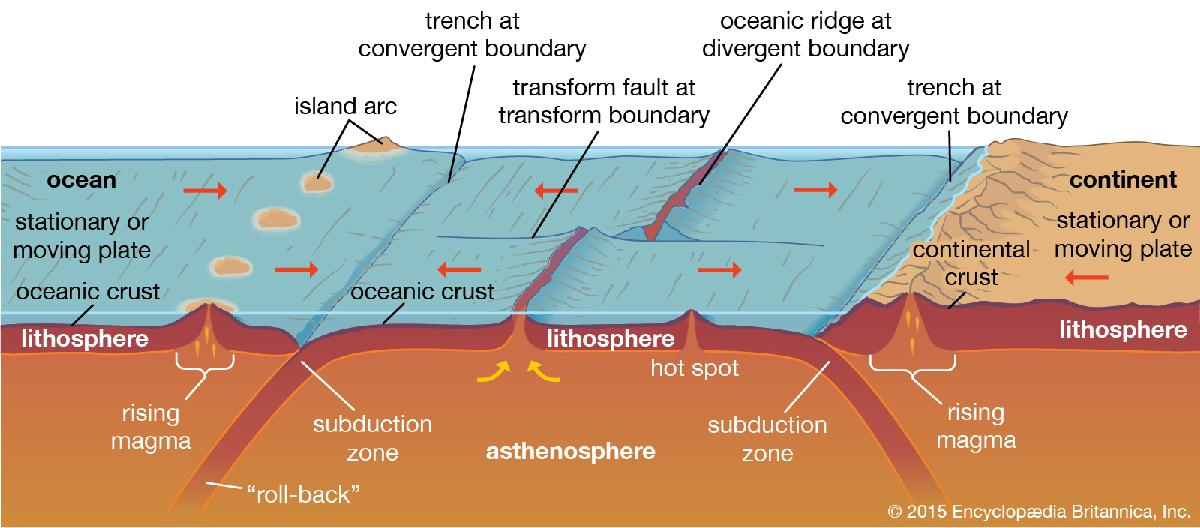

The figure above shows that the tectonic plates comprise the crust (oceanic or continental) and the **lithosphere**. The crust (oceanic or continental) is a compositionally distinct layer. In contrast the lithosphere has the same composition as the rest of the Earth mantle but distinguishes itself though it's mechanical properties. The viscosity of the mantle is exponentially dependent on temperature, and the lithosphere is cold enough to be so viscous that it acts rigid and is part of the tectonic plates. Therefore it is important for plate tectonic theory to understand the nature, in particular the thickness, of the oceanic lithosphere/plate. 

## Observational constraints on oceanic lithosphere

The two main data sets that contain information about the lithosphere are the heat flow at the sea floor and the bathymetry (depth) of the ocean as a function of its age. Below we plot the compilation of heat flow data from [Stein (1995)](https://agupubs.onlinelibrary.wiley.com/doi/abs/10.1029/RF001p0144) and bathymetry from [Parson and Sclater (1977)](http:// https://doi.org/10.1029/JB082i005p00803).

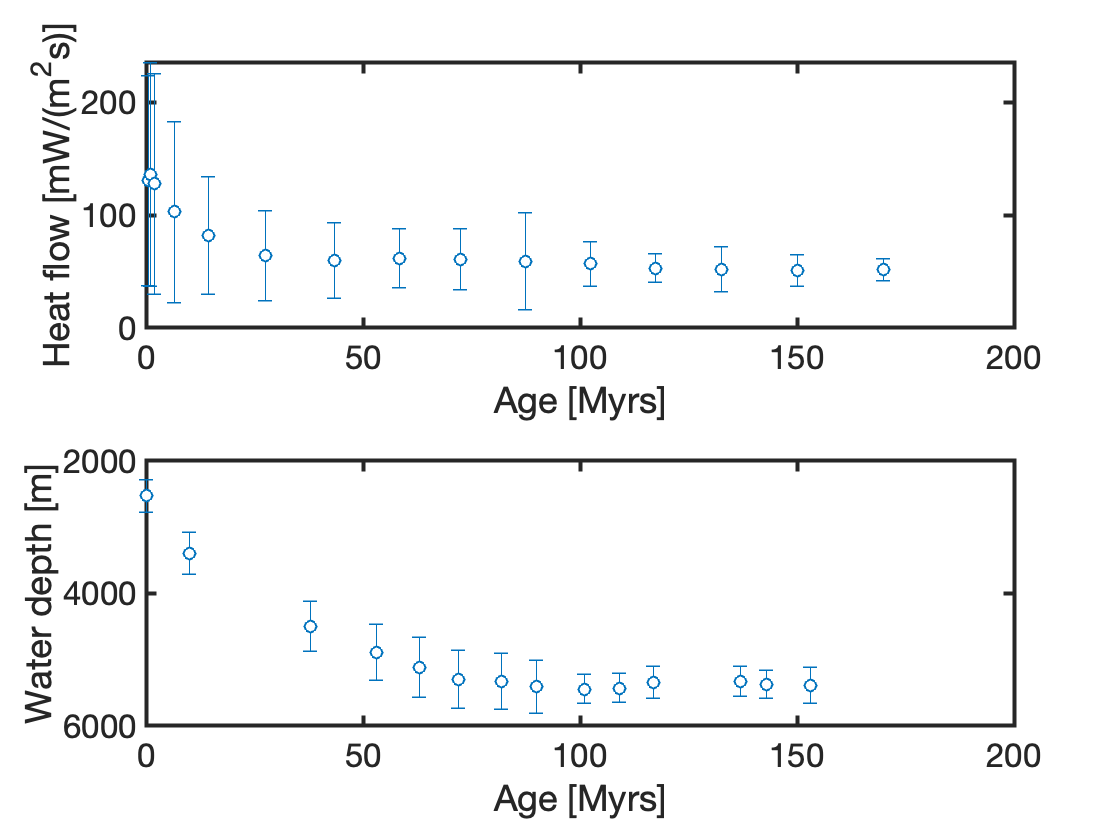

load ocean_heat_flow.mat
subplot 211
errorbar([age_min+age_max]/2,q_ave,q_std,'o','markerfacecolor','w')
xlabel 'Age [Myrs]', ylabel 'Heat flow [mW/(m^2s)]', xlim([0 200])
subplot 212
load ocean_bathymetry.mat
errorbar(age_bath,bath_ave,bath_std,'o','markerfacecolor','w')
xlabel 'Age [Myrs]', ylabel 'Water depth [m]'
set(gca,'ydir','reverse'), xlim([0 200])

The main observation is that heat flow declines monotonically from the ridge (zero age) and ocean depth increases monotonically away from the ridge. However, at large ages both heat flow and depth seem to become constant. This is an important observation that has been the source of much discussion and two competing models as we will see below. Since we have been modeling heat conduction, we will look at the ocean heat flow below. 

## Halfspace cooling model ([Davis and Lister 1974](https://doi.org/10.1016/0012-821X(74)90180-0))

The simplest model is that of a cooling half-space that translates away from the ridge at a constant velocity and has a constant surface temperature, $T_s$, and constant temperature beneath the ridge, $T_R$. For a ridge spreading at constant rate we can assume steady state, so that the governing equation is given by

$\nabla\cdot\left[\mathbf{v}\,T-k\nabla T\right]=f_s$ on the domain $x\in\left[0, \, \infty\left) \times z\in\left[0, \, \infty\left) $

 with boundary conditions $T(0,z) = T_R$ and $T(x,0) = T_s$, where $z$ is the depth below the seafloor. 

To make the problem tractable Davis and Lister make two three important assumptions:

- Conduction is pre-dominantly vertical, so that $\partial T/\partial x\approx 0$.

- Flow is predominantly horizontal and constant, so that $\mathbf{v} = (v,\,0)^T$.

- Domain is homogeneous (neglect crustal properties).

- Heat production is negligible, $f_s\approx 0$.

With these assumptions the governing equation reduces to

$v\frac{\partial T}{\partial x}-k\frac{\partial^2T}{\partial z^2}=0$ on $x\in\left[0, \, \infty\left) \times z\in\left[0, \, \infty\left) $

introducing the age of the plate, $t = x/v$, we recover the standard 1D heat equation on an *infinite* domain

$\frac{\partial T}{\partial t}-k\frac{\partial^2}{\partial z^2}=0$ on $t\geq0\times z\in\left[0, \, \infty\left) $

with the initial condition $T(z,0)=T_R$ and the boundary condition $T(0,t) = T_s$. The analytic solution for the temperature is given by the error function

$T(x,t) = T_R + (T_R-T_S)\mathrm{erf}\left(\frac{z}{\sqrt{4 k t}}\right)= T_R + (T_R-T_S)\mathrm{erf}\left(\frac{z}{\sqrt{4 k x/v}}\right)$.

The corresponding heat flux at the seabed is given by

$q_s=\kappa(T_r-T_s)\frac{1}{\sqrt{\pi k t}} = \kappa(T_r-T_s)\sqrt{\frac{v}{\pi k t}} $.

%% Parameters for the Earth's mantle from Stein 1995 - table 2
yr2s = 60^2*24*365.25; % [s/yr]
kappa = 3.0;      % [W/(m K)] thermal coductivity
cp = 1.171e3;       % [J/(kg K)] specific heat capacity 
rho = 3300;         % [kg/m^3] density
k = kappa/(rho*cp)  % [m^2/s] thermal diffusivity

k = 7.7634e-07

Ts = 0;
Tr = 1120;
T_hs = @(z,t) Ts + (Tr-Ts)*erf(z./sqrt(4*k*t));
q_hs = @(t)  kappa*(Tr-Ts)./sqrt(pi*k*t);

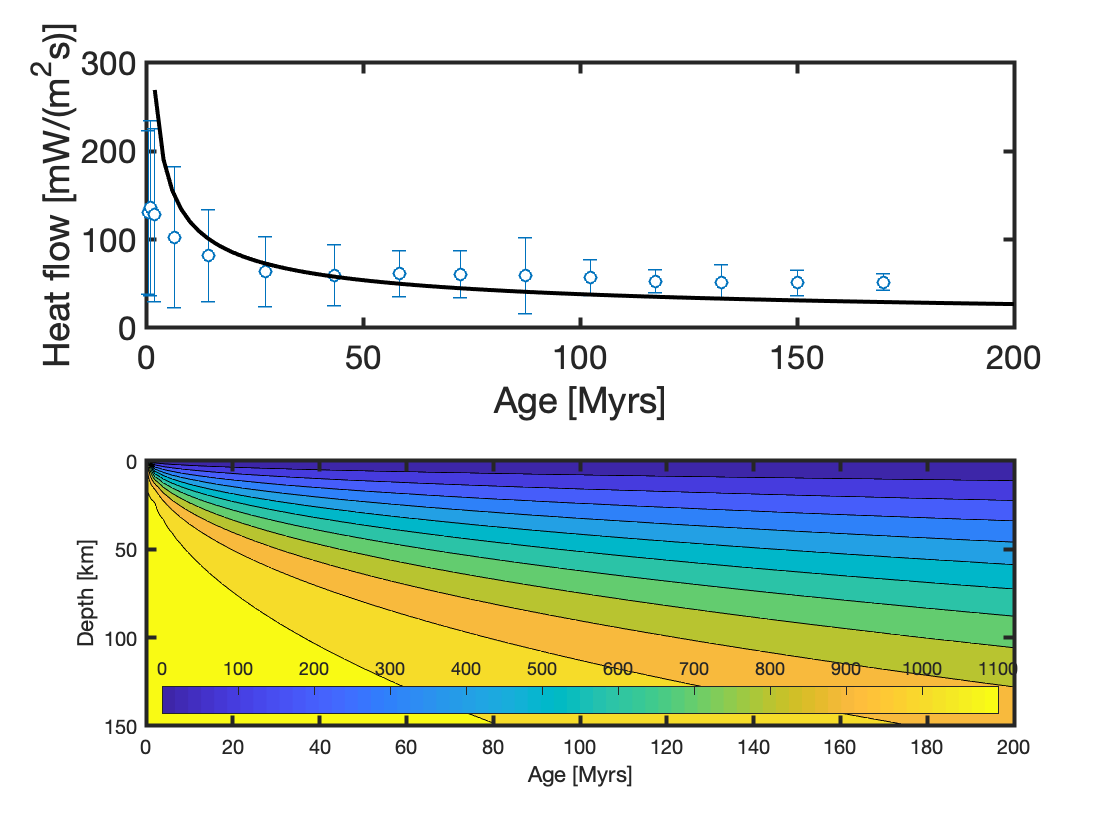

% Plot solution
tmax = 200e6*yr2s;
zmax = 150e3; 
t = linspace(0,tmax,100);
z = linspace(0,zmax,100);
[tt,zz] = meshgrid(t,z);
figure
subplot 211
errorbar([age_min+age_max]/2,q_ave,q_std,'o','markerfacecolor','w'), hold on
plot(t/1e6/yr2s,q_hs(t)*1e3,'k-')
xlabel 'Age [Myrs]', ylabel 'Heat flow [mW/(m^2s)]', xlim([0 200])

subplot 212
contourf(tt/1e6/yr2s,zz/1e3,T_hs(zz,tt),[0:100:1300])
colorbar('location','south')
xlabel 'Age [Myrs]'
ylabel 'Depth [km]'
set(gca,'ydir','reverse')

## Plate cooling model ([McKenzie 1964](https://doi-org.ezproxy.lib.utexas.edu/10.1029/JZ072i024p06261))

The half space model is not consistent with the constant heat flux observed in old ocean floor (> 100 Ma). This propmeted the development of the plate model that assumes a oceanic lithosphere of constant thickness with constant basal temperature. Hence the governing equations are

$\nabla\cdot\left[\mathbf{v}\,T-k\nabla T\right]=f_s$ on the domain $x\in\left[0, \, \infty\left) \times z\in\left[0, \, l\left]$

with boundary conditions $T(0,z) = T_R$, $T(x,0) = T_s$ and $T(x,l) = T_R$.

This, of course, forces the isotherms to become horizontal and the heat flow to become constant away from the ridge. To make the problem analytically tractable the classic plate model makes the same assuptions as the cooling half space model, namely:

- Conduction is pre-dominantly vertical, so that $\partial T/\partial x\approx 0$.

- Flow is predominantly horizontal and constant, so that $\mathbf{v} = (v,\,0)^T$.

- Domain is homogeneous (neglect crustal properties).

- Heat production is negligible, $f_s\approx 0$.

These assumptions together with the substitution, $t = x/v$, lead to the following 1D heat equation on a *finite* domain

$\frac{\partial T}{\partial t}-k\frac{\partial^2}{\partial z^2}=0$ on $t\geq0\times z\in\left[0, \, l\left]$

with inital and boundary conditions $T(0,z) = T_R$, $T(t,0) = T_s$ and $T(t,l) = T_R$. In this case, the analytic solution for the temperature is given by Fourier series


$$T = T_S+(T_R-T_S)\left[\frac{z}{l}+\frac{2}{\pi}\sum_{n=1}^\infty\frac{1}{n}\exp\left(-\frac{k(n\pi)^2t}{l^2}\right)\sin\left(\frac{n\pi z}{l}\right)\right]$$


and the heat flux at the sea floor is given by

$q_s=\frac{\kappa (T_R-T_S)}{l}\left[1+2\sum_{n=1}^\infty\exp\left(-\frac{k(n\pi)^2t}{l^2}\right)\right]$.

Below we plot this solution for the values chosen by [Stein and Stein (1995)](http://www.nature.com/articles/359123a0) to fit the observed heat flow for old oceanic plates. Due to the constant plate thickness, the heat flow in old oceanic plates is constant by construction.

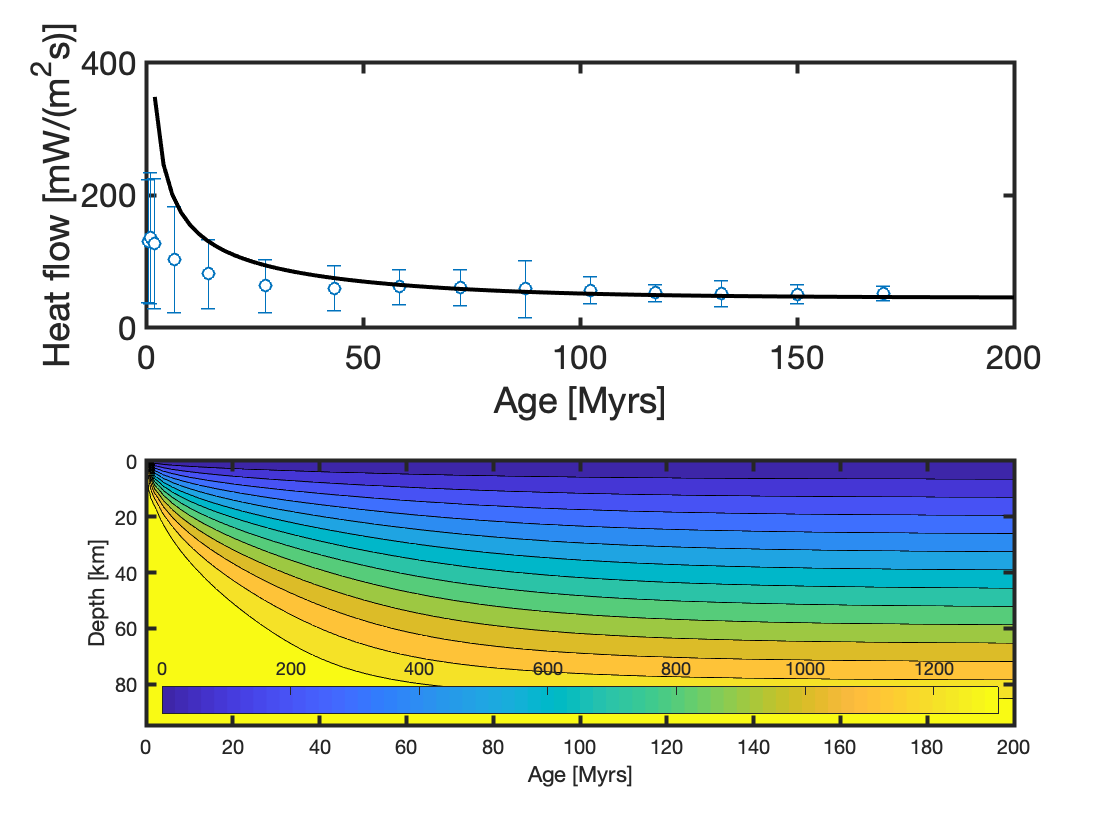

Tr = 1450; % basal temperature
zmax = 95e3; % Plate thickness
[tt,zz,T_pm,t,qs_pm] = plate_model(Tr,Ts,tmax,zmax,100,100,125,k,kappa);

figure
subplot 211
errorbar([age_min+age_max]/2,q_ave,q_std,'o','markerfacecolor','w'), hold on
plot(t/1e6/yr2s,qs_pm*1e3,'k-')
xlabel 'Age [Myrs]', ylabel 'Heat flow [mW/(m^2s)]', xlim([0 200])

subplot 212
contourf(tt/1e6/yr2s,zz/1e3,T_pm,[0:100:1300])
colorbar('location','south')
xlabel 'Age [Myrs]'
ylabel 'Depth [km]'
set(gca,'ydir','reverse')

Not surprisingly the model manages to choose three paramters ($k$, $\kappa$, $l$) to fit a single observable the approximately constant heat flow at large time of ~50 mW/(m$^2$s). In that sense, it is an improvement over the half space cooling model, though at the cost of an arbitrary assumption, i.e., the finte plat thickness. For young oceanic crus,t the plate model model overpredicts the heat flux similar to the halfspace cooling model. Typically, this is ascribed to the venting of large amounts of heat at [hydrothermal vents](https://en.wikipedia.org/wiki/Hydrothermal_vent) near the MOR, which is not reflected in the heat flow measurements. However, the near ridge heatflow in both models is an artefact of the largely arbitrary left boundary condition, . 

function [tt,zz,T,t,qs] = plate_model(Tr,Ts,tmax,zmax,Nt,Nz,N,k,kappa)
DT = Tr-Ts;
t = linspace(0,tmax,Nt);
z = linspace(0,zmax,Nz);
[tt,zz] = meshgrid(t,z);
T = Ts + DT*zz/zmax;
for n = 1:N
    T = T + 2*DT/(n*pi)*sin(n*pi*zz/zmax).*exp(-k*(n*pi)^2*tt/zmax^2);
end
qs = kappa*DT/zmax;
for n = 1:N
    qs = qs + 2*kappa*DT/zmax*exp(-k*(n*pi)^2*t/zmax^2);
end
qs(1) = nan;
end